original = imread('stavebnica.jpg');
if size(original,3)>1
   original = rgb2gray(original); 
end
corners_cus = shiThomasiFeatures(original, 5);
imshow(original);
% figure
sc_cus = corners_cus.selectStrongest(79);
hold on
plot(sc_cus.Location(:,1),sc_cus.Location(:,2),'k','Marker','^','LineStyle','none');
hold off

corners_cv = detectMinEigenFeatures(original);
sc_cv = corners_cv.selectStrongest(79);
sc_cv.Location = round(sc_cv.Location)

sc_cv =   79×1 cornerPoints array with properties:

    Location: [79×2 single]
      Metric: [79×1 single]
       Count: 79


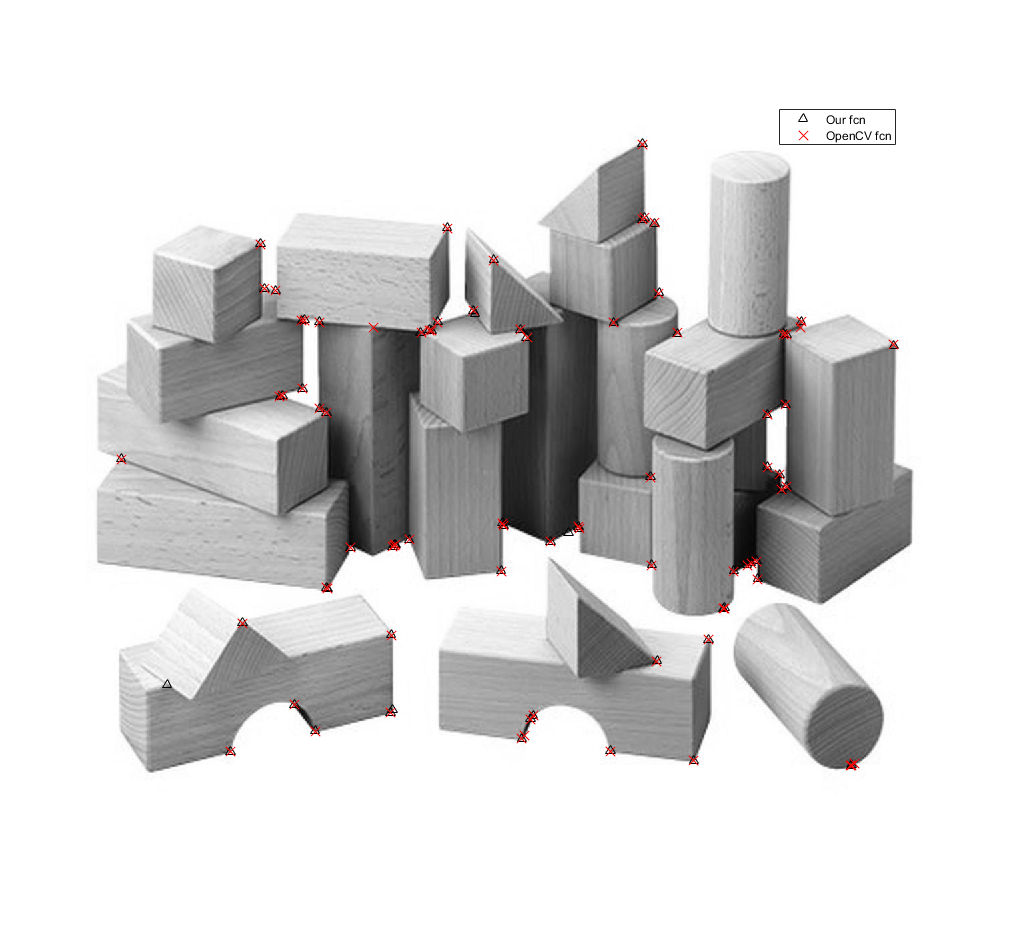

hold on
% plot(corners.selectStrongest(10));
plot(sc_cv.Location(:,1),sc_cv.Location(:,2),'r','Marker','x','LineStyle','none', 'MarkerSize',10);
hold off
legend("Our fcn", "OpenCV fcn", "Location","best")